# Skin Lesion Image and Metadata Classification via CNN Transfer Learning

Group Members: Brian John Braddock, James Bratt, Wilson Huang, Julie Vu

Course: BME 3053C Computer Applications for BME

Term: Fall 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: bjohn.braddock@ufl.edu

Last updated: December 6, 2021

## Load dataset

Our dataset comes from the ISIC **2019** Challenge dataset, which can be found on the [ISIC website](https://challenge.isic-archive.com/data) ([download link](https://isic-challenge-data.s3.amazonaws.com/2019/ISIC_2019_Training_Input.zip)), or on this [kaggle dataset](https://www.kaggle.com/andrewmvd/isic-2019). 

BCN_20000 Dataset: (c) Department of Dermatology, Hospital Clínic de Barcelona

HAM10000 Dataset: (c) by ViDIR Group, Department of Dermatology, Medical University of Vienna; https://doi.org/10.1038/sdata.2018.161

MSK Dataset: (c) Anonymous; https://arxiv.org/abs/1710.05006 ; https://arxiv.org/abs/1902.03368

dataLocation = "Dataset/ISIC_2019_Training_Input"; % Relative path to folder where the .jpg files are located
labelsLocation = "Dataset/groundtruth_categorical.csv"; % Relative path to the categorical labels .csv file

#### Create a datastore for the raw images. 

An image datastore is an object type which stores lists of file locations/names rather than the files themselves. Since we are working with a ~10GB dataset, this is almost necessary. 

See [imageDatstore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) in the MATLAB docs for more info. 

image_datastore = imageDatastore(dataLocation); % Initialize the imageDatastore with the files in the dataLocation
num_images = length(image_datastore.Files);

### Import metadata

metadataLocation = "Dataset/ISIC_2019_Training_Metadata.csv";
metadataTable = readtable(metadataLocation);

sex = categorical(metadataTable.sex);
location = categorical(metadataTable.anatom_site_general);
age = metadataTable.age_approx;

#### Import ground truth labels

groundtruth = readtable(labelsLocation); % Read the converted .csv file as a table
image_datastore.Labels = categorical(groundtruth.category); % Set the Labels of the imageDatastore to a categorical type array from the category column of .csv

Display some images with their true label

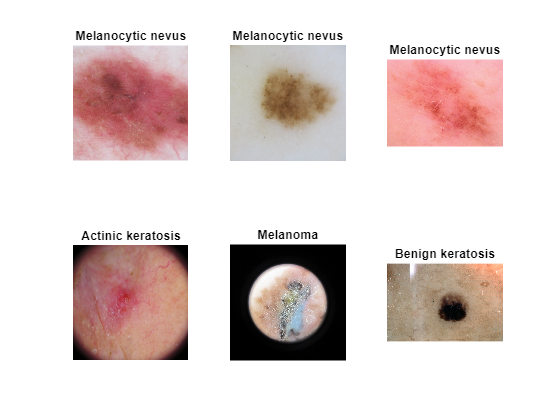

figure;
for i = 1:6
    subplot(2,3,i);
    sample_idx = randi(num_images);
    imshow(readimage(image_datastore, sample_idx)); % Extract the image file from the imageDatastore and imshow it
    title(image_datastore.Labels(sample_idx));
end

Remove datapoints with missing metadata

missing = isundefined(sex) | isundefined(location) | isnan(age);

sex = sex(~missing);
location = location(~missing);
age = age(~missing);

image_datastore = subset(image_datastore, ~missing);

## Create Feature Matrix

### Convert categorical features to logical format

X_sex = sex == 'female';
X_location = onehotencode(location, 2);

Scale age data between 0 and 1.

age = normalize(age, 'range');

### Combine into feature matrix

X = [age, X_sex, X_location];

### Create Combined Datastore

dsFeatures = arrayDatastore(X);
dsResponses = arrayDatastore(image_datastore.Labels);
dsCombined = combine(image_datastore, dsFeatures, dsResponses);

subsetIdxs = splitlabels(image_datastore.Labels, [0.8, 0.1]);

trainDs = subset(dsCombined,subsetIdxs{1});
valDs = subset(dsCombined, subsetIdxs{2});
testDs = subset(dsCombined, subsetIdxs{3});

### Balance training set by oversampling underrepresented classes

As shown below, the ISIC dataset is highly imbalanced. 

Of our 8 classes, ~50% are of label 'Melanocytic nevus' (medical term for the common birthmark), ~18% are of label 'Melanoma'. Furthermore, our 4 smallest classes account for less than 8% of the total dataset combined. This is a problem as our model will heavily prefer to predict the larger classes purely by statistical likeliness. 

trainingLabelCounts = countEachLabel(trainDs.UnderlyingDatastores{1}) % Get the number of images that belong to each class label

trainingLabelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis           676 
    Basal cell carcinoma       2596 
    Benign keratosis           1866 
    Dermatofibroma              188 
    Melanocytic nevus          8506 
    Melanoma                   3477 
    Squamous cell carcinoma     498 
    Vascular lesion             178 


To address this issue, we ***oversample*** the dataset - create duplicate entries for each image in the smaller classes to make up the difference in size. We have provided a separate helper function [oversampleCombinedDatastore.m](matlab:open('./oversampleCombinedDatastore.m')) to do this, and return the balanced combinedDatastore.

targetLabelCount = max(trainingLabelCounts.Count); % the ceiling for oversampleDataset to duplicate each class label to
balTrainDs = oversampleCombinedDatastore(trainDs, targetLabelCount);


Each category should have the same number of samples as the highest category (Mel. nevus). 

labelCounts = countEachLabel(balTrainDs.UnderlyingDatastores{1})

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis          8506 
    Basal cell carcinoma       8506 
    Benign keratosis           8506 
    Dermatofibroma             8506 
    Melanocytic nevus          8506 
    Melanoma                   8506 
    Squamous cell carcinoma    8506 
    Vascular lesion            8506 


### Augment Images

inputSize = [224 224];
% Create the imageDataAugmenter with the desired augmentation effects.
% These effects are each applied at random.
% See the docs for in-depth descriptions of each Name, Value option pair. 
augmenter = imageDataAugmenter( ...
    "RandXReflection", true, ... 
    "RandYReflection", true, ...
    "RandRotation", [-180 180], ... % Rotate an image between +-180 degrees
    "RandScale", [0.8 1.5], ...     % Scale an image from 80% to 150% of its original size
    "RandXShear", [0 15], ...       % Shear an image horizontally and vertically within the range 0 degrees to 30 degrees
    "RandYShear", [0 15]);          

trainTransform = transform(balTrainDs.UnderlyingDatastores{1},@(x) preprocessImage(x,inputSize, augmenter));
trainAug = trainTransform.UnderlyingDatastores{1};

trainDs = combine(trainTransform, trainDs.UnderlyingDatastores{2}, trainDs.UnderlyingDatastores{3});

#### Resize the validation set

Any image going through the GoogLeNet model needs to be 224x224, so we should resize the validation and test sets as well. 

valTransform = transform(valDs.UnderlyingDatastores{1},@(x) imresize(x,inputSize));
valAug = valTransform.UnderlyingDatastores{1};

valDs = combine(valTransform, valDs.UnderlyingDatastores{2}, valDs.UnderlyingDatastores{3});

#### Resize the test set

testTransform = transform(testDs.UnderlyingDatastores{1},@(x) imresize(x,inputSize));
testAug = testTransform.UnderlyingDatastores{1};

testDs = combine(testTransform, testDs.UnderlyingDatastores{2}, testDs.UnderlyingDatastores{3});

## Import and modify pretrained Neural Network

classes = categories(testAug.Labels);
numClasses = numel(classes);

To make GoogLeNet compatible with our training data, we change the last two layers to output classifications for our 8 labels. 

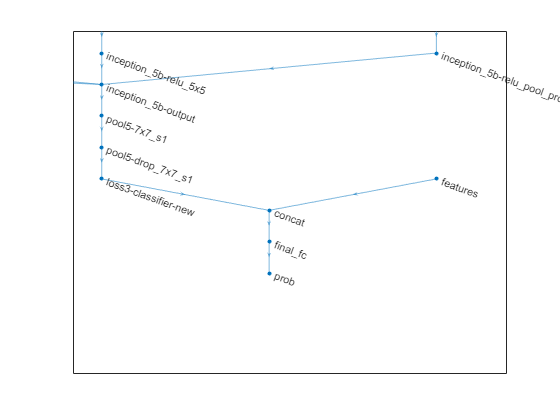

net = googlenet; % Import the googlenet DAGNet object from the Deep Learning Toolbox
lgraph = layerGraph(net); % Convert to a layerGraph object, which contains all the data for each layer of the Neural Network



concatLayer = concatenationLayer(1, 2, 'Name', 'concat');
lgraph = addLayers(lgraph, concatLayer);

finalFc = fullyConnectedLayer(numClasses,"Name","final_fc"); % Create a new fullyConnectedLayer with nodes for each class 
lgraph = addLayers(lgraph, finalFc);

featureInLayer = featureInputLayer(10, 'name', 'features');
lgraph = addLayers(lgraph, featureInLayer);


newLoss3 = fullyConnectedLayer(10,"Name","loss3-classifier-new"); % Create a new fullyConnectedLayer with nodes for each class 
lgraph = replaceLayer(lgraph,"loss3-classifier",newLoss3); % Replace the existing fullyConnectedLayer


lgraph = disconnectLayers(lgraph, 'loss3-classifier-new', 'prob');
lgraph = connectLayers(lgraph, 'loss3-classifier-new', 'concat/in1');
lgraph = connectLayers(lgraph, 'features', 'concat/in2');
lgraph = connectLayers(lgraph, 'concat', 'final_fc');
lgraph = connectLayers(lgraph, 'final_fc', 'prob');

lgraph = removeLayers(lgraph, 'output');

figure;
plot(lgraph);

xlim([2.914 4.211])
ylim([-2.2 8.7])


dlnet = dlnetwork(lgraph);

### Create a custom training loop

#### Specify training options

executionEnvironment = "auto";
plots = "training-progress";
verbose = true;


checkpointPath = fullfile(pwd, "Checkpoints", "dlnet");
if ~exist(checkpointPath, "dir")
    mkdir(checkpointPath);
end

numEpochs = 100;
miniBatchSize = 64;

learnRate = 0.01;
decay = 0.01;
momentum = 0.9;
l2Regularization = 0.0001;


validationsPerEpoch = 4;
validationPatienceEpochs = 7;

iterationsPerEpoch = floor(numel(trainAug.Files)/miniBatchSize);
validationFrequency = floor(iterationsPerEpoch/validationsPerEpoch);
verboseFrequency = 50;
validationPatience = validationsPerEpoch * validationPatienceEpochs;

### Train Model

If you do not wish to train the network on your computer, we have provided a model that we trained previously in the GitHub repository. Instead of running the training sections, call the following command and skip to the Validation step.


mbq = minibatchqueue(trainDs, ...
    'MiniBatchSize', miniBatchSize, ...
    'MiniBatchFcn', @preprocessMiniBatch,...
    'MiniBatchFormat', {'SSCB', 'CB', ''});


Training Progress Plot

if plots == "training-progress"

    figure;
    subplot(2,1,1);
    lineAccuracyTrain = animatedline('Color', [0 0.4470 0.7410]);
    ylabel("Accuracy");
    grid on;

    subplot(2,1,2);
    lineLossTrain = animatedline('Color', [0.85 0.325 0.098]);
    xlabel('Iteration');
    ylabel('Loss');
    grid on;

    if ~isempty(valDs)
        subplot(2,1,1);
        lineAccuracyValidation = animatedline('Color', 'b');

        subplot(2,1,2);
        lineLossValidation = animatedline('Color', 'b');
    end
end
velocity = [];

earlyStop = false;
if isfinite(validationPatience)
    validationLosses = inf(1, validationPatience);
end

disp("|======================================================================================================================|")
disp("|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |")
disp("|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |")
disp("|======================================================================================================================|")

iteration = 0;
start = tic;


% Loop over epochs
for epoch = 1:numEpochs
    %Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches
    while hasdata(mbq) && ~earlyStop
        iteration = iteration + 1;

        % Read next minibatch of data
        [dlX1, dlX2, dlY] = next(mbq);
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX1 = gpuArray(dlX1);
            dlX2 = gpuArray(dlX2);
        end

        % Evaluate model gradients, state, and loss using dlfeval and 
        % the modelGradients function and update the network state.
        [gradients, state, lossTrain, accuracyTrain] = dlfeval(@modelGradients, dlnet, dlX1, dlX2, dlY, classes);
        dlnet.State = state;

        %%%% L2 Regularization
        idx = dlnet.Learnables.Parameter == "Weights";
        gradients(idx,:) = dlupdate( @(g, w) g + l2Regularization * w, gradients(idx,:), dlnet.Learnables(idx,:));

        % Update the network parameters using SGDM optimizer.
        [dlnet, velocity] = sgdmupdate(dlnet, gradients, velocity, learnRate, momentum);





        % Validation checkpoint
        if (iteration == 1) || (mod(iteration, validationFrequency) == 0)

            mbqVal = minibatchqueue(valDs, ...
               'MiniBatchSize', miniBatchSize, ...
               'MiniBatchFcn', @preprocessMiniBatch, ...
               'MiniBatchFormat', {'SSCB', 'CB', ''});
            
            
            [predictions, predCorr, ~, lossValidation] = modelPredictions(dlnet, mbqVal, classes);
            
            accuracyValidation = mean(predictions == predCorr);

            if isfinite(validationPatience)
                validationLosses = [validationLosses lossValidation];
                if min(validationLosses) == validationLosses(1)
                    earlyStop = true;
                else
                    validationLosses(1) = [];
                end
            end

            if ~isempty(checkpointPath)
                D = datestr(now,'yyyy_mm_dd__HH_MM_SS');
                filename = checkpointPath + "\dlnet_checkpoint__" + string(iteration) + "__" + string(D) + ".mat";
                save(filename, "dlnet", "lossValidation");
            end
        end



        
        if plots == "training-progress"
            D = duration(0,0, toc(start), 'Format', 'hh:mm:ss');
            
            addpoints(lineAccuracyTrain, iteration, accuracyTrain);
            addpoints(lineLossTrain, iteration, lossTrain);

            if ~isempty(valDs) && (iteration == 1 || mod(iteration, validationFrequency) == 0)
                addpoints(lineAccuracyValidation, iteration, accuracyValidation);
                addpoints(lineLossValidation, iteration, lossValidation);
            end
            


            title('Epoch: ' + string(epoch) + ', Elapsed: ' + string(D));
            drawnow;
        end

        if verbose && (iteration == 1 || mod(iteration, verboseFrequency) == 0)
            D = duration(0,0, toc(start), 'Format', 'hh:mm:ss');

            if isempty(valDs) || mod(iteration, validationFrequency) ~= 0
                accuracyValidation = "";
                lossValidation = "";
            end

            disp("| " + ...
                pad(string(epoch),7,'left') + " | " + ...
                pad(string(iteration),11,'left') + " | " + ...
                pad(string(D),14,'left') + " | " + ...
                pad(string(accuracyTrain),12,'left') + " | " + ...
                pad(string(accuracyValidation),12,'left') + " | " + ...
                pad(string(lossTrain),12,'left') + " | " + ...
                pad(string(lossValidation),12,'left') + " | " + ...
                pad(string(learnRate),15,'left') + " |")
        end

    end
end

disp("|======================================================================================================================|")

%save('dlnet.mat', 'dlnet');

## Evaluate model on Validation Set

mbqVal = minibatchqueue(valDs, ...
   'MiniBatchSize', miniBatchSize, ...
   'MiniBatchFcn', @preprocessMiniBatch, ...
   'MiniBatchFormat', {'SSCB', 'CB', ''});


[predictions, predCorr, scores, loss] = modelPredictions(dlnet, mbqVal, classes);

accuracy = mean(predictions == predCorr);


figure;
confusionchart(predCorr, predictions, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Validation Set - Accuracy: " + string(accuracy));

### Calculating Precision, Recall, & F1

confusion_matrix = confusionmat(predCorr, predictions);


correct = diag(confusion_matrix);

precision = correct./sum(confusion_matrix)';
recall = correct./sum(confusion_matrix, 2);
f1Scores = 2*(precision.*recall)./(precision + recall);

% disp(precision);
% disp(recall);
% disp(f1Scores);
valStats = table( ...
    [classes; "Average"], ...
    [precision; sum(precision)/numel(precision)], ...
    [recall; sum(recall)/numel(recall)], ...
    [f1Scores; sum(f1Scores)/numel(f1Scores)], ...
    'VariableNames', {'Class', 'Precision', 'Recall', 'F1Score'})

## Evaluate model on Test Set

mbqTest = minibatchqueue(testDs, ...
   'MiniBatchSize', miniBatchSize, ...
   'MiniBatchFcn', @preprocessMiniBatch, ...
   'MiniBatchFormat', {'SSCB', 'CB', ''});


[predictions, predCorr, scores, loss] = modelPredictions(dlnet, mbqTest, classes);

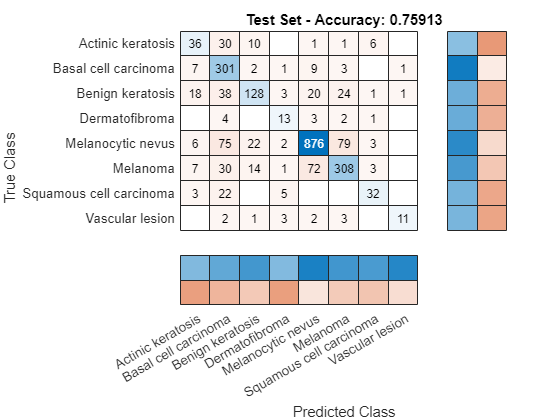


accuracy = mean(predictions == predCorr);


figure;
confusionchart(predCorr, predictions, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Test Set - Accuracy: " + string(accuracy));

### Calculating Precision, Recall, & F1

confusion_matrix = confusionmat(predCorr, predictions);


correct = diag(confusion_matrix);

precision = correct./sum(confusion_matrix)';
recall = correct./sum(confusion_matrix, 2);
f1Scores = 2*(precision.*recall)./(precision + recall);

% disp(precision);
% disp(recall);
% disp(f1Scores);
testStats = table( ...
    [classes; "Average"], ...
    [precision; sum(precision)/numel(precision)], ...
    [recall; sum(recall)/numel(recall)], ...
    [f1Scores; sum(f1Scores)/numel(f1Scores)], ...
    'VariableNames', {'Class', 'Precision', 'Recall', 'F1Score'})

testStats = 9×4 table
              Class              Precision    Recall     F1Score
    _________________________    _________    _______    _______

    "Actinic keratosis"           0.46753     0.42857     0.4472
    "Basal cell carcinoma"         0.5996     0.92901    0.72881
    "Benign keratosis"            0.72316     0.54936    0.62439
    "Dermatofibroma"              0.46429     0.56522     0.5098
    "Melanocytic nevus"           0.89115     0.82408     0.8563
    "Melanoma"                    0.73333     0.70805    0.72047
    "Squamous cell carcinoma"     0.69565     0.51613    0.59259
    "Vascular lesion"             0.84615         0.5    0.62857
    "Average"                     0.67761     0.62755    0.63852


### Define Image Augmentation Function

function imAug = preprocessImage(image, size, augmenter)
    
    imAug = imtranslate(image, [randi([-100 100]) randi([-75 75])]);
    imAug = augment(augmenter, imAug);
    imAug = imresize(imAug,size);
end

### Define a Model Gradients Function

function [gradients, state, loss, accuracy] = modelGradients(dlnet, dlX1, dlX2, Y, classes) 

    [dlYPred, state] = forward(dlnet, dlX1, dlX2);

    loss = crossentropy(dlYPred, Y);
    gradients = dlgradient(loss, dlnet.Learnables);

    YPredBatch = onehotdecode(dlYPred, classes, 1);
    YClass = onehotdecode(Y, classes, 1);
    accuracy = mean(YPredBatch == YClass);


    loss = double(gather(extractdata(loss)));
end




### Model Predictions Function

function  [classesPredictions,classCorr, scores, loss] = modelPredictions(dlnet, mbq, classes)

    classesPredictions = [];
    classCorr = [];
    scores = [];
    losses = [];

    while hasdata(mbq)
        

        [dlX1, dlX2, dlY] = next(mbq);

        dlYPred = predict(dlnet, dlX1, dlX2);

        lossBatch = crossentropy(softmax(dlYPred), dlY);
        losses = [losses; lossBatch];

        dlYScore = stripdims(dlYPred)';
        scores = [scores; dlYScore];

        YPredBatch = onehotdecode(dlYPred, classes, 1);
        classesPredictions = [classesPredictions, YPredBatch];
        
        Y = onehotdecode(dlY, classes, 1);
        classCorr = [classCorr, Y];

    end
    loss = mean(double(gather(extractdata(losses))));
end

### Define the Mini-Batch Preprocessing Function

function [X, features, Y] = preprocessMiniBatch(XCell,featuresCell, YCell)

    % Preprocess predictors.
    X = preprocessMiniBatchPredictors(XCell);
    
    features = cat(1, featuresCell{:})';
    % Extract label data from cell and concatenate.
    Y = cat(2,YCell{1:end});
    % One-hot encode labels.
    Y = onehotencode(Y,1);

end

### Define the Mini-Batch Predictors Preprocessing Function

function X = preprocessMiniBatchPredictors(XCell)

    % Concatenate.
    X = cat(4,XCell{1:end});

end